## Build two data sets: low and high noise

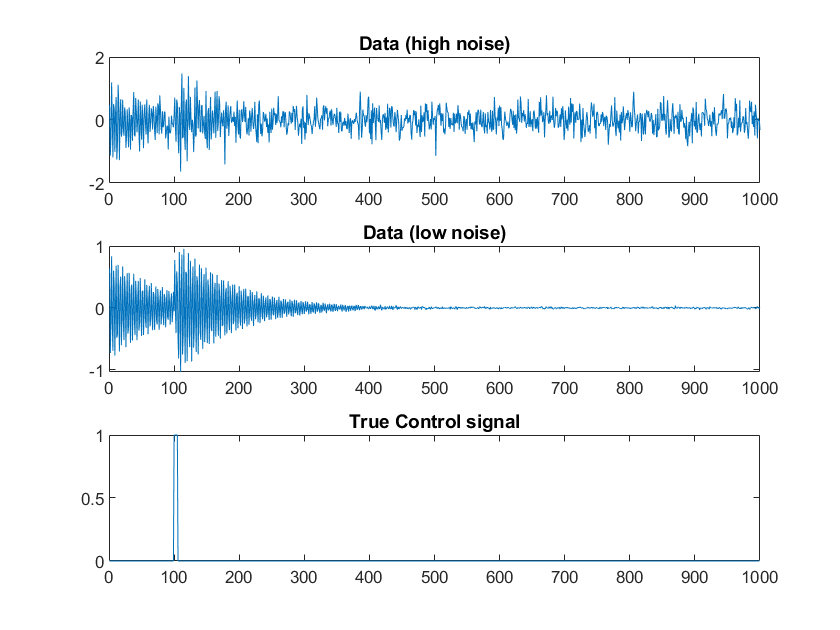

% Build example dynamics matrix
seed = 17;
n = 2;                  % Matrix size; should be even
m = 1000;               % Number of data points
eigenvalue_min = 0.95;  % Minimum eigenvalue; 1.0 = stable
[X_dmd, A] = test_dmd_dat(n, m, 0, eigenvalue_min, seed);

% Build random controller
ctr_timing = 100:105;
U = zeros(1,m-1);
U(ctr_timing) = 1.0;

% Generate controlled data
x0 = X_dmd(:,1);
B = ones(n,1);
X_true = real(calc_reconstruction_dmd(x0, [], A, B, U));
% Add noise
high_noise = 0.3;
X_high = X_true + high_noise*randn(size(X_true));
low_noise = 0.01;
X_low = X_true + low_noise*randn(size(X_true));

% Plot
figure;

subplot(3,1,1)
plot(1:m,X_high(1,:))
title("Data (high noise)")

subplot(3,1,2)
plot(1:m,X_low(1,:))
title("Data (low noise)")

subplot(3,1,3)
plot(1:m-1,U)
title("True Control signal")

## Learn the control signal 1: acf

% Returns a data class with control signals of increasing sparsity
settings = struct('r_ctr',1, ... % Number of control signals to search for
                  'verbose',false, ... 
                   'num_iter',100); % Number of iterations
path_high_noise = learn_control_signals(X_high, settings);

All control signals are 0. Stopping early (this is nothing to worry about)


path_low_noise = learn_control_signals(X_low, settings);

All control signals are 0. Stopping early (this is nothing to worry about)


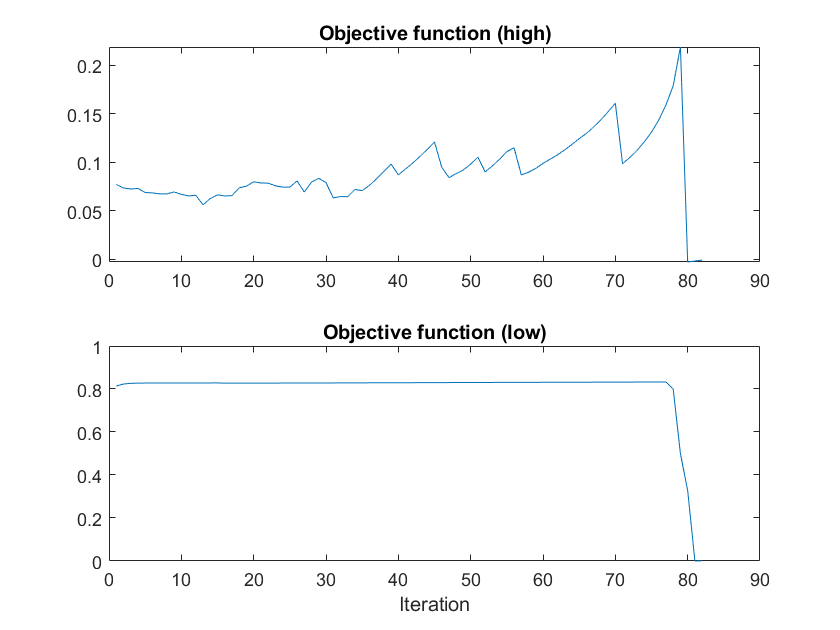


% Calculate best control signal
objective_function = 'acf';
path_high_noise.calc_best_control_signal(objective_function)
path_low_noise.calc_best_control_signal(objective_function)

best_U_high = path_high_noise.U;
best_U_low = path_low_noise.U;

% Plot
objective_vals_high = path_high_noise.objective_values;
objective_vals_low = path_low_noise.objective_values;

figure;
subplot(2,1,1)
plot(objective_vals_high)
title('Objective function (high)')
subplot(2,1,2)
plot(objective_vals_low)
title('Objective function (low)')
xlabel('Iteration')

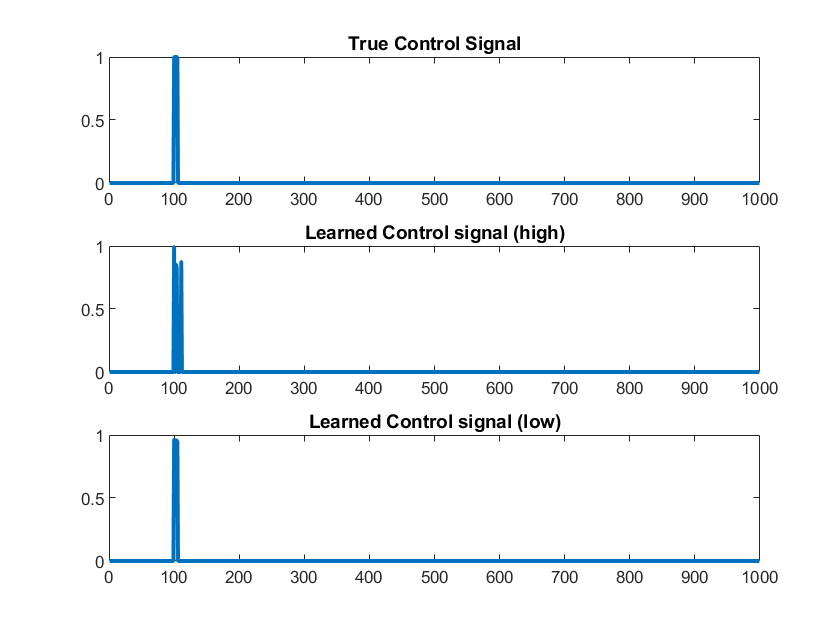


figure;
subplot(3,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(3,1,2)
plot(best_U_high, 'linewidth', 2)
title("Learned Control signal (high)")
subplot(3,1,3)
plot(best_U_low, 'linewidth', 2)
title("Learned Control signal (low)")

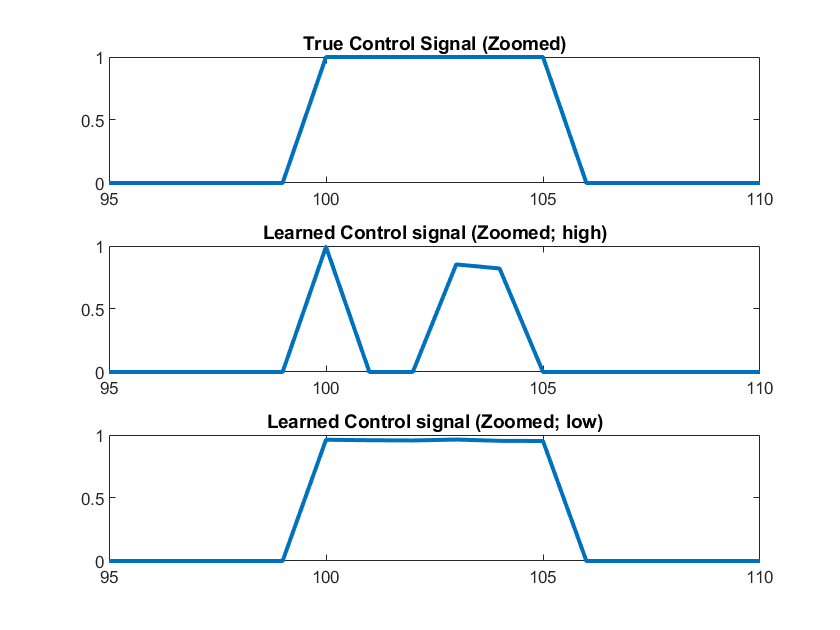


figure;
ind = 95:110;
subplot(3,1,1)
plot(ind, U(ind), 'linewidth', 2)
title("True Control Signal (Zoomed)")
subplot(3,1,2)
plot(ind, best_U_high(ind), 'linewidth', 2)
title("Learned Control signal (Zoomed; high)")
subplot(3,1,3)
plot(ind, best_U_low(ind), 'linewidth', 2)
title("Learned Control signal (Zoomed; low)")

## Learn the control signal 2: aic

% Use paths from above

% Calculate best control signal
objective_function = 'aic';
path_high_noise.calc_best_control_signal(objective_function)

path_low_noise.calc_best_control_signal(objective_function)

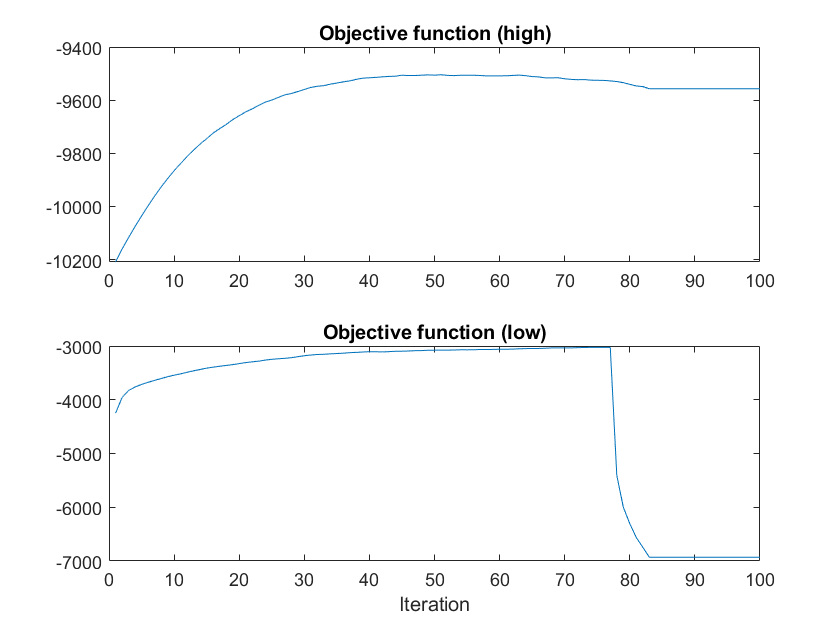


best_U_high = path_high_noise.U;
best_U_low = path_low_noise.U;

% Plot
objective_vals_high = path_high_noise.objective_values;
objective_vals_low = path_low_noise.objective_values;

figure;
subplot(2,1,1)
plot(objective_vals_high)
title('Objective function (high)')
subplot(2,1,2)
plot(objective_vals_low)
title('Objective function (low)')
xlabel('Iteration')

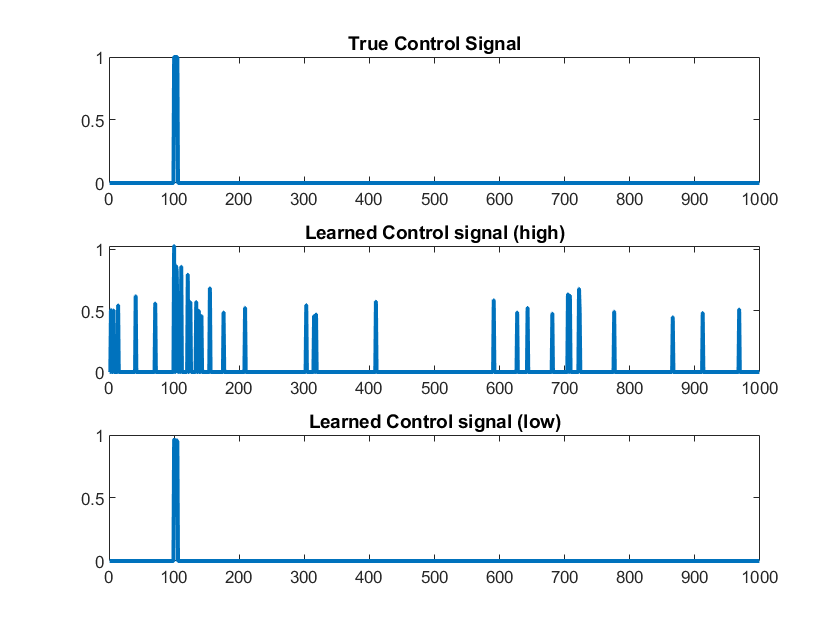


figure;
subplot(3,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(3,1,2)
plot(best_U_high, 'linewidth', 2)
title("Learned Control signal (high)")
subplot(3,1,3)
plot(best_U_low, 'linewidth', 2)
title("Learned Control signal (low)")

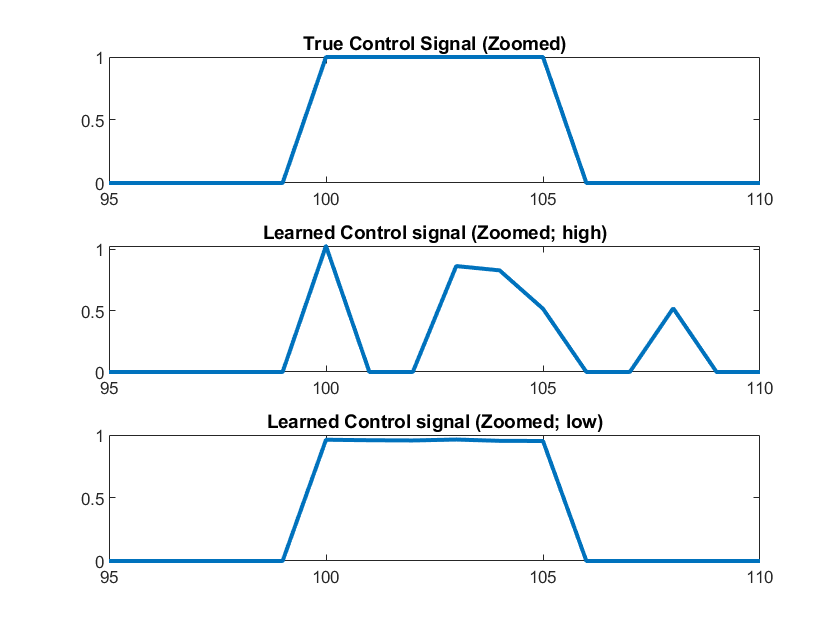


figure;
ind = 95:110;
subplot(3,1,1)
plot(ind, U(ind), 'linewidth', 2)
title("True Control Signal (Zoomed)")
subplot(3,1,2)
plot(ind, best_U_high(ind), 'linewidth', 2)
title("Learned Control signal (Zoomed; high)")
subplot(3,1,3)
plot(ind, best_U_low(ind), 'linewidth', 2)
title("Learned Control signal (Zoomed; low)")

## Learn the control signal 3: aic with sparsity parameter

% Use paths from above

% Calculate best control signal
objective_function = 'aic_window';
lambda = {3};
path_high_noise.calc_best_control_signal(objective_function, lambda)

path_low_noise.calc_best_control_signal(objective_function, lambda)

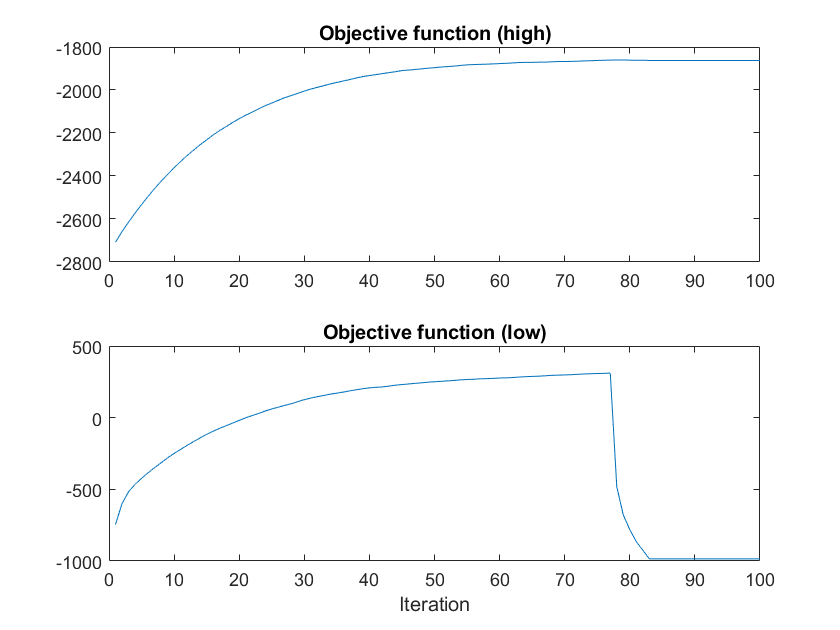


best_U_high = path_high_noise.U;
best_U_low = path_low_noise.U;

% Plot
objective_vals_high = path_high_noise.objective_values;
objective_vals_low = path_low_noise.objective_values;

figure;
subplot(2,1,1)
plot(objective_vals_high)
title('Objective function (high)')
subplot(2,1,2)
plot(objective_vals_low)
title('Objective function (low)')
xlabel('Iteration')

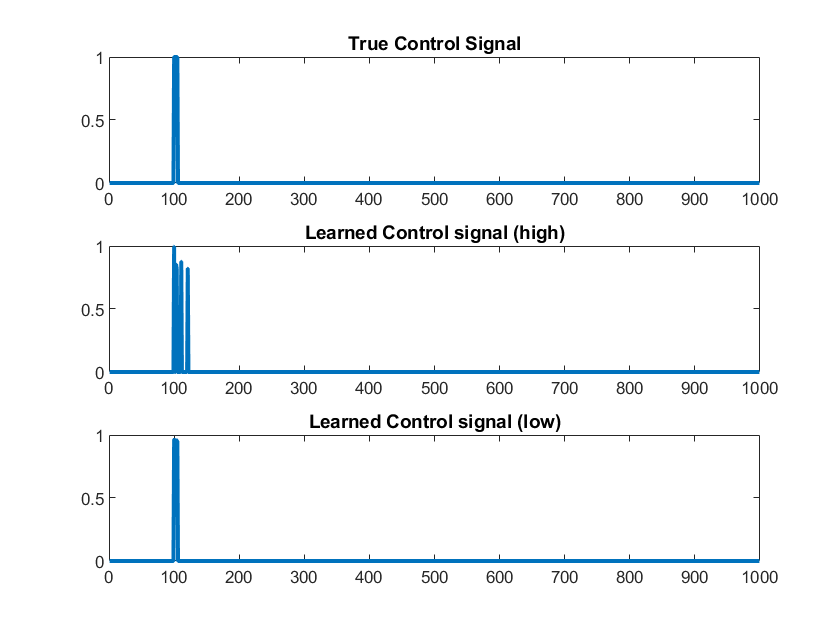


figure;
subplot(3,1,1)
plot(U, 'linewidth', 2)
title("True Control Signal")
subplot(3,1,2)
plot(best_U_high, 'linewidth', 2)
title("Learned Control signal (high)")
subplot(3,1,3)
plot(best_U_low, 'linewidth', 2)
title("Learned Control signal (low)")

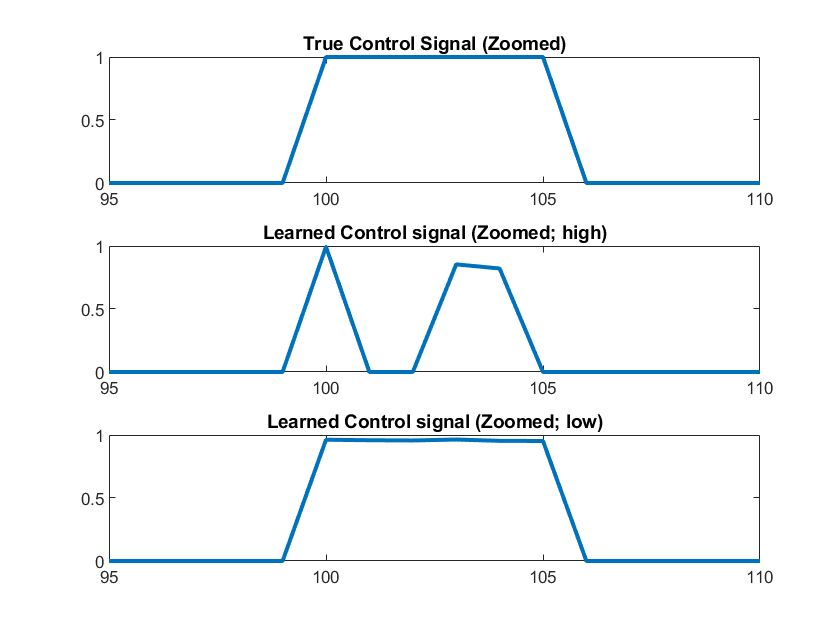


figure;
ind = 95:110;
subplot(3,1,1)
plot(ind, U(ind), 'linewidth', 2)
title("True Control Signal (Zoomed)")
subplot(3,1,2)
plot(ind, best_U_high(ind), 'linewidth', 2)
title("Learned Control signal (Zoomed; high)")
subplot(3,1,3)
plot(ind, best_U_low(ind), 'linewidth', 2)
title("Learned Control signal (Zoomed; low)")